sistema = tf(1, [1 5 6 0])

sistema =
 
          1
  -----------------
  s^3 + 5 s^2 + 6 s
 
Continuous-time transfer function.



Kp = 30;

%calcula as margens de ganho e fase
%Para mG é frequência que passa o módulo 0
%Para mF é a frequência que passa antes de -180°
[mG, mF,Wmg, Wmf] = margin(Kp*sistema) 

mG =      1


mF =      4.637268572235020e-07


Wmg =    2.449489742783178


Wmf =    2.449489722549276



%valor da margem de ganho em dB
mg_DB = 20*log(mG)

mg_DB =      0


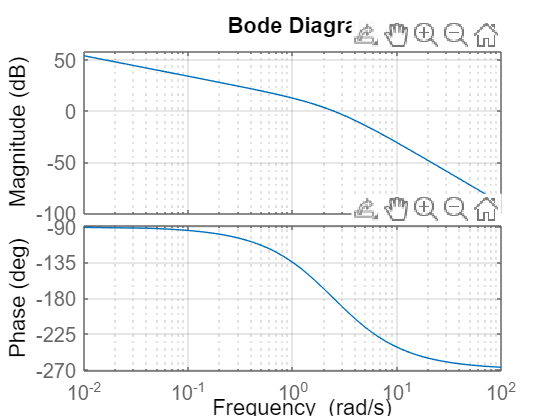

bode(Kp*sistema)
grid on;